# ENME462 Studio 6 Steady-State Error

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

**Steady-state error** is the difference between the **input** and **output** for a prescribed test input as $t\rightarrow\infty$

$e_{ss}$in terms of forward transfer function G(s) in unity feedback systems

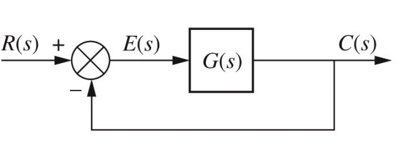


$$E(s)=R(s)-C(S)=R(s)-\frac{G(s)}{1+G(s)}R(s)=\frac{1}{1+G(s)}R(s)$$



$$e_{ss}=e(t\rightarrow\infty)=\lim_{s\rightarrow0}sE(s)=\lim_{s\rightarrow0}\frac{sR(s)}{1+G(s)}$$


## **Different Input Signals r(t)**

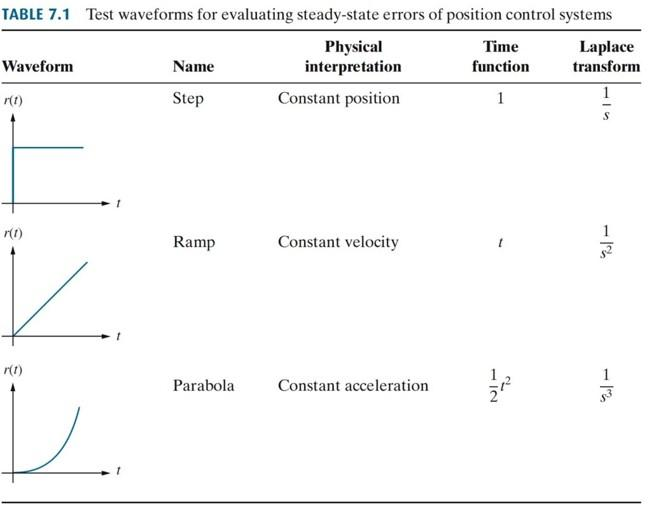

***Step input:  ***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s)}{1+G(s)}=\frac{1}{1+\lim_{s\rightarrow0}G(s)}=\frac{1}{1+K_p}$$
 

position constant: $K_p=\lim_{s\rightarrow0}G(s)$

***Ramp input:***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s^2)}{1+G(s)}=\lim_{s\rightarrow0}\frac{1}{s+sG(s)}=\frac{1}{\lim_{s\rightarrow0}sG(s)}=\frac{1}{K_v}$$


velocity constant: $K_v=\lim_{s\rightarrow0}sG(s)$

***Parabola input:***


$$e_{ss}=e_{step}(\infty)=\lim_{s\rightarrow0}\frac{s(1/s^3)}{1+G(s)}=\lim_{s\rightarrow0}\frac{1}{s^2+s^2G(s)}=\frac{1}{\lim_{s\rightarrow0}s^2G(s)}=\frac{1}{K_a}$$


acceleration constant: $K_a=\lim_{s\rightarrow0}s^2G(s)$

## System Type Number


$$G(s)=\frac{q(s)}{s^Np(s)}=\frac{(s+z_1)(s+z_2)...}{s^N(s+p_1)(s+p_2)...}$$


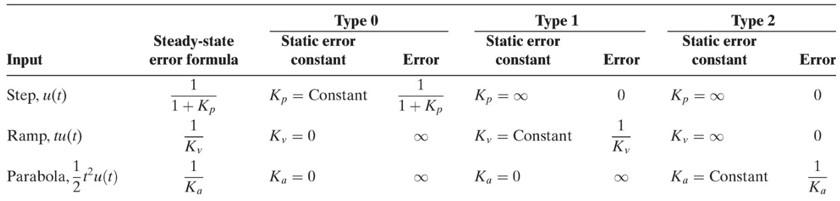

**Example 1.** A space station shown below in (a) will keep its solar arrays facing the sun using a solar tracking control system. The simplified block diagram in (b) represents the solar tracking control system that is used to rotatethe solar arrays. 

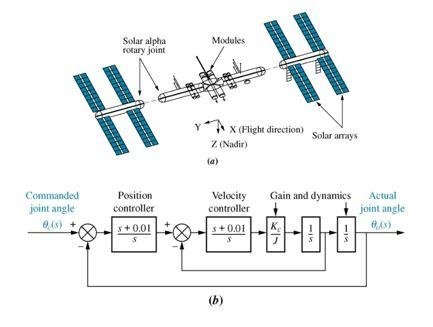

For the inner loop

$G_e(s)=\frac{K(s+0.01)/s^2}{1+K(s+0.01)/s^2}=\frac{K(s+0.01)}{s^2+Ks+0.01K}$ , where $K=\frac{K_c}{J}$

The inner closed loop transfer function 


$$G(s)=\frac{s+0.01}{s}\cdot G_e(s)\cdot \frac{1}{s}=K\frac{(s+0.01)^2}{s^2(s^2+Ks+0.01K)}$$


System is Type 2.


$$K_p=\infty \qquad\rightarrow \qquad e_{step}(\infty)=\frac{1}{1+K_p}=\frac{1}{1+\infty}=0\\
K_v=\infty \qquad \rightarrow \qquad e_{ramp}(\infty)=\frac{1}{K_v}=\frac{1}{\infty}=0\\
K_a=\lim_{s\rightarrow0}s^2G(s)=0.01 \quad \rightarrow \quad e_{parabola}(\infty)=\frac{1}{K_a}=\frac{1}{0.01}=100$$
          

s = zpk('s');
K = 0.8;
Ge = feedback((s + 0.01)/s * K * 1/s,1)


Ge =
 
       0.8 (s+0.01)
  ----------------------
  (s+0.01013) (s+0.7899)
 
Continuous-time zero/pole/gain model.



G = (s + 0.01)/s * Ge * 1/s % open loop transfer function


G =
 
        0.8 (s+0.01)^2
  --------------------------
  s^2 (s+0.01013) (s+0.7899)
 
Continuous-time zero/pole/gain model.



T = feedback(G,1)           % closed loop transfer function 


T_s =
 
                    0.8 (s+0.01)^2
  ---------------------------------------------------
  (s^2 + 0.0201s + 0.000101) (s^2 + 0.7799s + 0.7922)
 
Continuous-time zero/pole/gain model.



E = 1 - T                   % transfer function between input and error


E_s =
 
              s^2 (s+0.7899) (s+0.01013)
  ---------------------------------------------------
  (s^2 + 0.0201s + 0.000101) (s^2 + 0.7799s + 0.7922)
 
Continuous-time zero/pole/gain model.



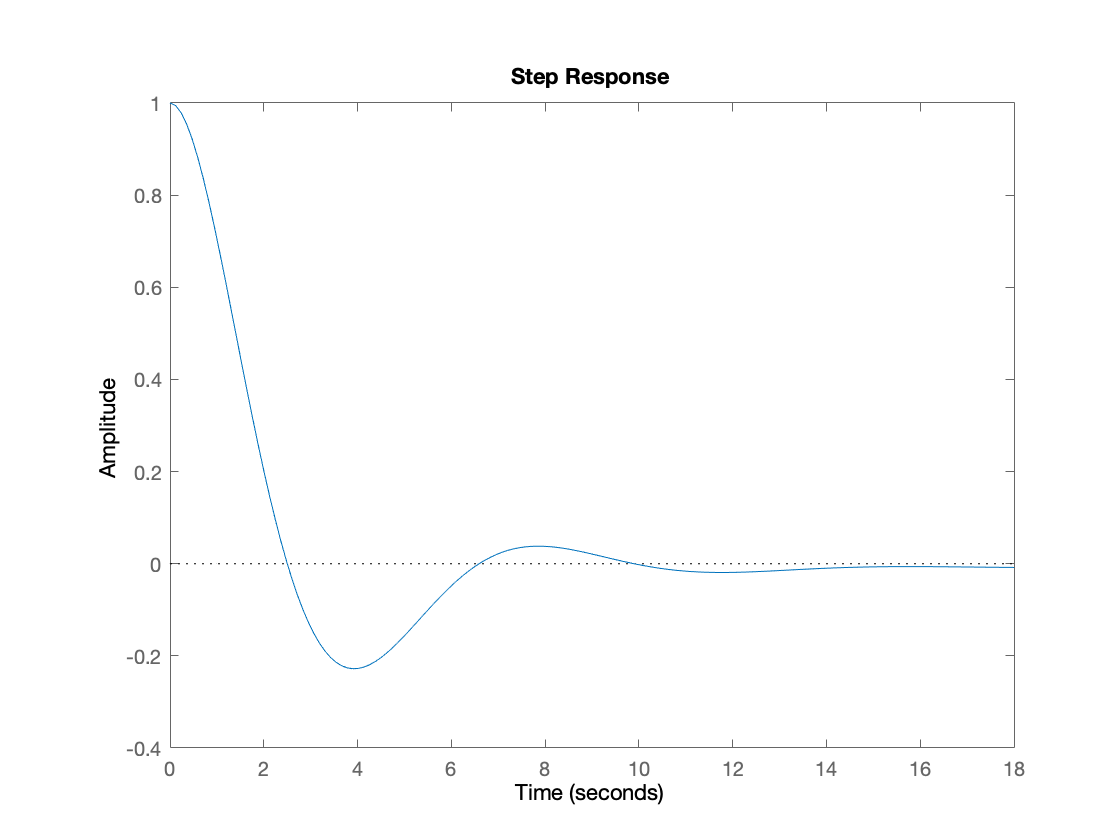

step(E)

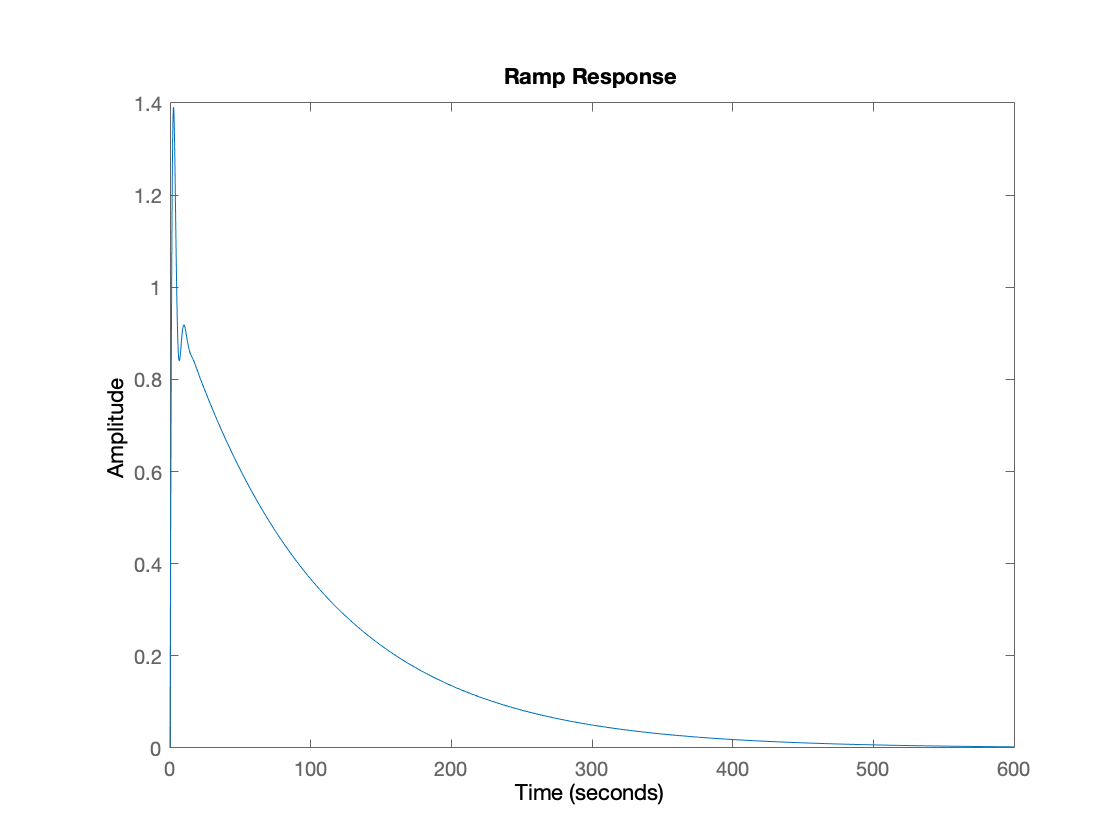

step(E*1/s)
title('Ramp Response')

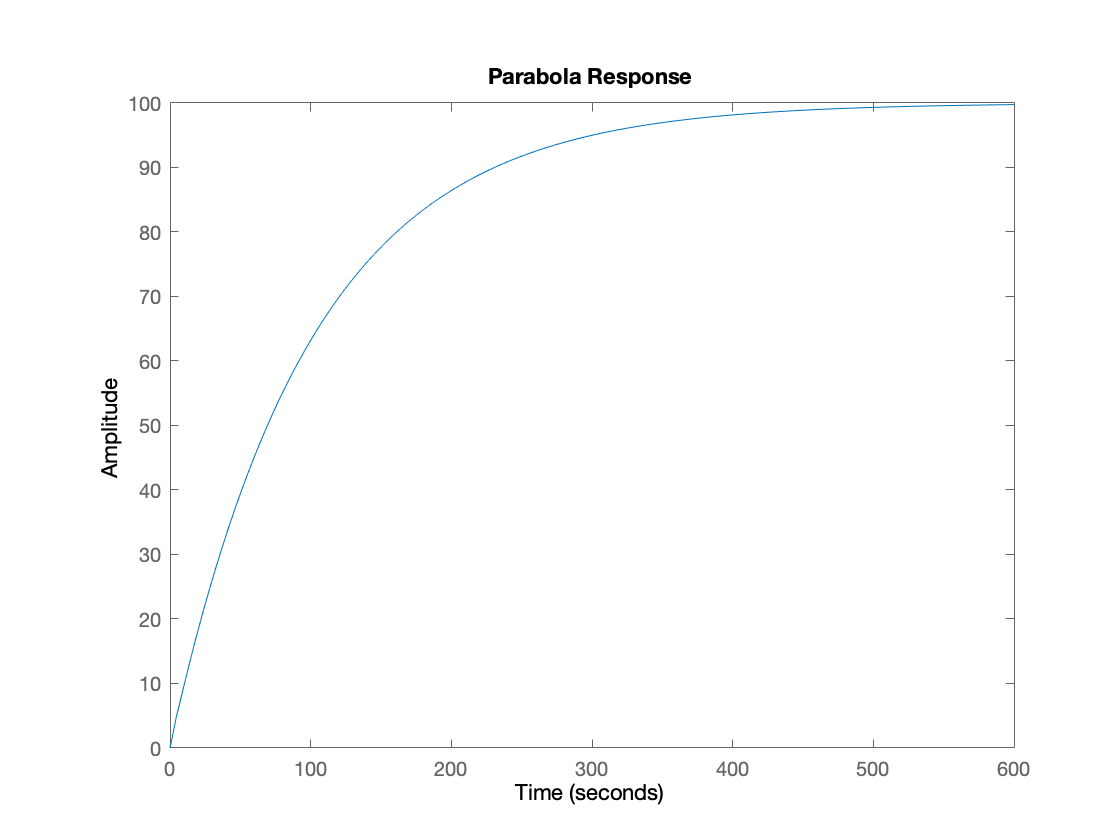

step(E*1/s*1/s)
title('Parabola Response')

**Example 2.** A boat is circling a ship that is using a tracking radar. The speed of the boat is 20 knots, and it is circling the ship at a distance of 1 nautical mile, as shown below. Find the value of K so that the boat is kept in the cneter of the radar beam with no more than 0.1-degree error.

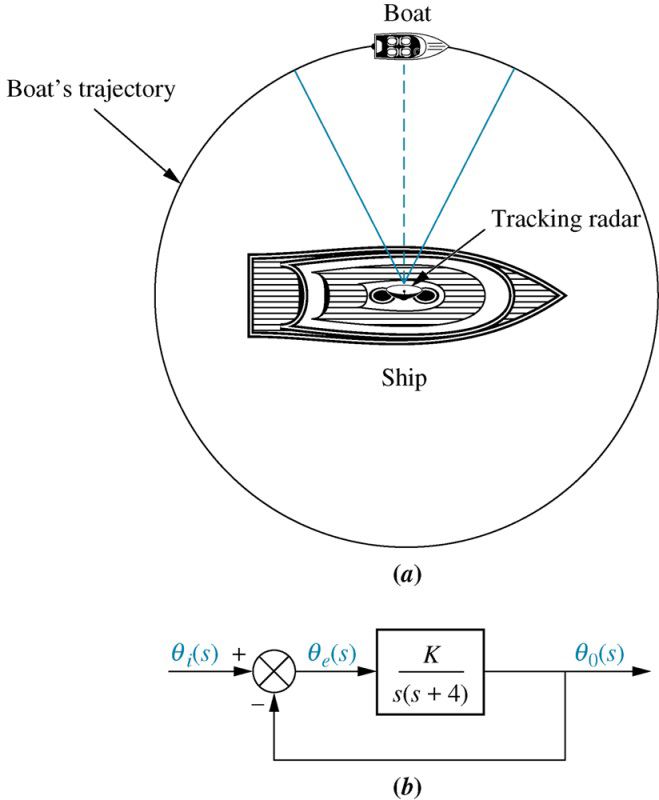

circiumference: = $2\pi \cdot r$ = $2\pi$ nautical mile 

therefore, boat makes 1 revolution in $\frac{2\pi}{20}\cdot\frac{\text{nautical mile}}{\text{knots}}=0.314 (\text{hr})$

Angular velocity: $\omega=\frac{1}{0.314}\cdot\frac{\text{rev}}{\text{hr}}=\frac{2\pi}{0.314\cdot 3600}\cdot\frac{rad}{sec}=5.56\cdot10^{-3}(\text{rad/sec})$

For $0.1^{o}$error, $e(\infty)=\frac{1/10^o}{360^o}\cdot 2\pi (\text{rad})=\frac{5.56\cdot10^{-3}}{K_v}$, and $K_v=\lim_{s\rightarrow0}sG(s)=\lim_{s\rightarrow0}\frac{sK}{s(s+4)}=\frac{K}{4}$

hence, $K=12.76$

s = zpk('s');
K = 12.76;
G = K / (s*(s+4));
T = feedback(G,1)


T =
 
        12.76
  ------------------
  (s^2 + 4s + 12.76)
 
Continuous-time zero/pole/gain model.



E = 1 - T


E =
 
       s (s+4)
  ------------------
  (s^2 + 4s + 12.76)
 
Continuous-time zero/pole/gain model.



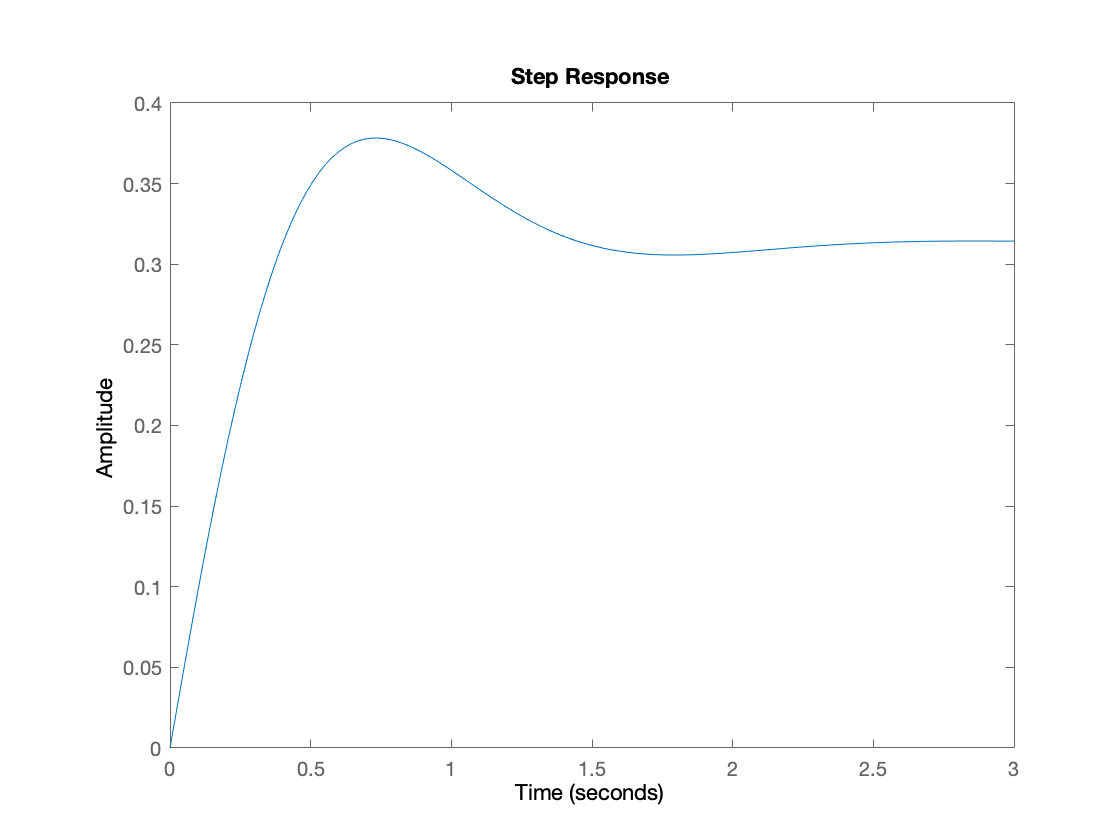

step(E/s)

**Exercise 1.** Develop a MATLAB script to model the solar tracking control system in Example 1 above. Let $K_c/J=0.8$. Use your MATLAB script to verify the steady-state error that were obtained analytically in Example 1 above for unit step, unit ramp and unit parabola inputs.

**Exercise 2.** In the figure below let $G(s)=5$ and $P(s)=\frac{7}{s+2}$.

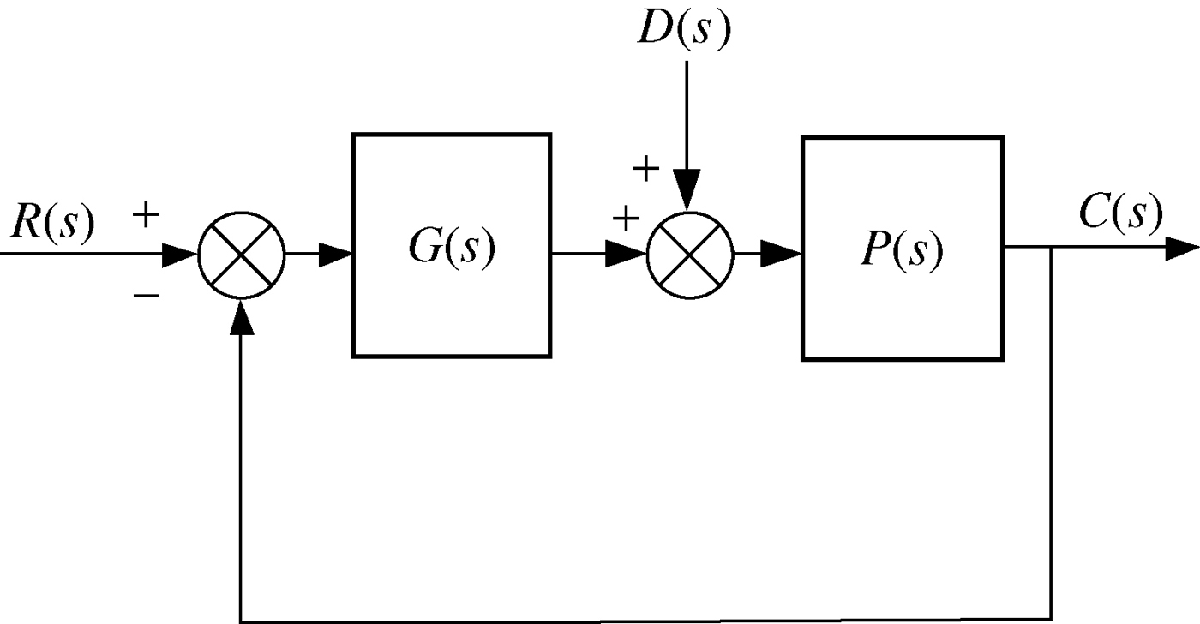

a) Calculate the steady-state error due to a command input $R(s)=\frac{3}{s}$ and $D(s)=0$. Verfity your answer with MATLAB.

b) Calculate the steady-state error due to a command input $R(s)=0$ and $D(s)=-\frac{1}{s}$. Verfity your answer with MATLAB.

c) Calculate the steady-state error due to a command input $R(s)=\frac{3}{s}$ and $D(s)=-\frac{1}{s}$. Verfity your answer with MATLAB.